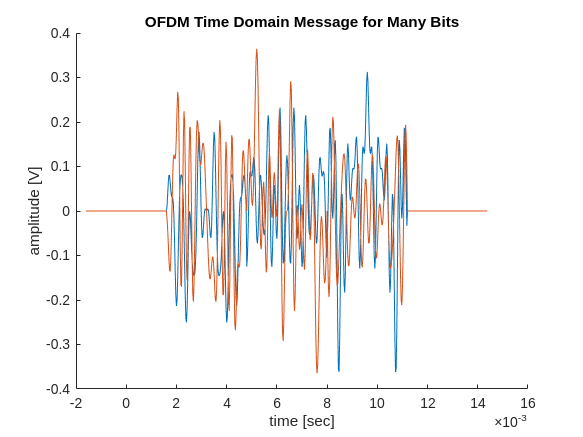

% Adam Nichols
% Prof. Jacobs
% ECE 1898
% 3 February 2025

% modulate/demodulate a message using a simple OFDM scheme

% reset the workspace
clear, clc

% generate a message of random bits
num_symbols = 3;
num_carriers = 32;
num_bits = num_carriers * num_symbols;
bits = RandomBits(num_bits);

% parallelize bits into bitstreams
num_symbols = ceil(num_bits / num_carriers);
if mod(num_bits,num_carriers) > 0
    bits_padded = [bits; zeros(num_carriers-mod(num_bits,num_carriers),1)];
else
    bits_padded = bits;
end

data = reshape(bits_padded,num_carriers,[]);

% modulate OFDM symbols from the fourier coefficients
fourier_coeffs = data*2 - 1;
s_coeffs = zeros(num_carriers,num_symbols);
% perform IFFT
for i = 0:num_symbols-1
    s_coeffs(i*num_carriers+1:(i+1)*num_carriers) = ifft(fourier_coeffs(i*num_carriers+1:(i+1)*num_carriers));
end

% define timing parameters of the OFDM signal
bandwidth = 1e4;
guard_carriers = 1/4*num_carriers;
bandwidth_useful = bandwidth/2;
bandwidth_guard = guard_carriers*bandwidth/num_carriers;
baseband_bandwidth = bandwidth_useful + bandwidth_guard;
fs = bandwidth;
ts = 1/fs;
symboltime = ts * num_carriers;
symbolrate = 1/symboltime;
t = transpose((0:num_carriers*num_symbols-1)*ts);

% perform upsampling
upsamp = 4;
fs_upsamp = upsamp*fs;
ts_upsamp = ts/upsamp;
s_upsamp = zeros(num_carriers*upsamp,num_symbols);
for i = 0:num_symbols-1
    s_curr = s_coeffs(i*num_carriers+1:(i+1)*num_carriers);
    if num_symbols > 1
        s_curr = transpose(s_curr);
    end
    s_curr_triple = [s_curr; s_curr; s_curr];
    s_curr_triple_upsamp = resample(s_curr_triple,upsamp,1);
    s_curr_upsamp = s_curr_triple_upsamp(upsamp*num_carriers+1:2*upsamp*num_carriers);

    % filter each symbol with ideal lowpass brick wall
    [f_curr, spec_curr_lp] = GetSpectrum(s_curr_upsamp,fs_upsamp);
    spec_curr_lp(abs(f_curr)>baseband_bandwidth) = 0;
    % perform ifft to get back time domain message
    s_curr_lp = ifft(ifftshift(fs_upsamp*spec_curr_lp));

    s_upsamp((i*num_carriers*upsamp+1:(i+1)*num_carriers*upsamp)) = s_curr_lp;
end

% get sizes
[s_upsamp_symbol_length, s_upsamp_num_symbols] = size(s_upsamp);

% concatenate all OFDM symbols without guard intervals or filtering
s_upsamp_vec = reshape(s_upsamp,[],1);

% zero pad the message
s_upsamp_vec = [zeros(num_carriers*upsamp,1); s_upsamp_vec; zeros(num_carriers*upsamp,1)];

% generate time vector
n_upsamp = transpose((1:length(s_upsamp_vec))-num_carriers*upsamp/2-1);
t_upsamp = ts_upsamp * n_upsamp;

% plot this upsampled, concatenated version of OFDM
figure(1)
clf
hold on
plot(t_upsamp,real(s_upsamp_vec))
plot(t_upsamp,imag(s_upsamp_vec))
title("OFDM Time Domain Message for Many Bits")
xlabel("time [sec]")
ylabel("amplitude [V]")

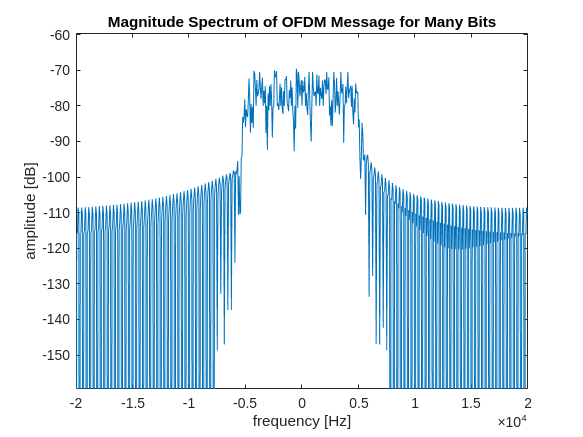


% get the spectrum of the concatednated signal
[f_upsamp_all, spec_upsamp_all] = GetSpectrum(s_upsamp_vec,fs_upsamp);
mag_spec_upsamp_all = 20*log10(abs(spec_upsamp_all));

% plot the spectrum of the upsampled signal
figure(2)
clf
plot(f_upsamp_all,mag_spec_upsamp_all)
title("Magnitude Spectrum of OFDM Message for Many Bits")
xlabel("frequency [Hz]")
ylabel("amplitude [dB]")
ylim([max(mag_spec_upsamp_all)-90, max(mag_spec_upsamp_all)+10])

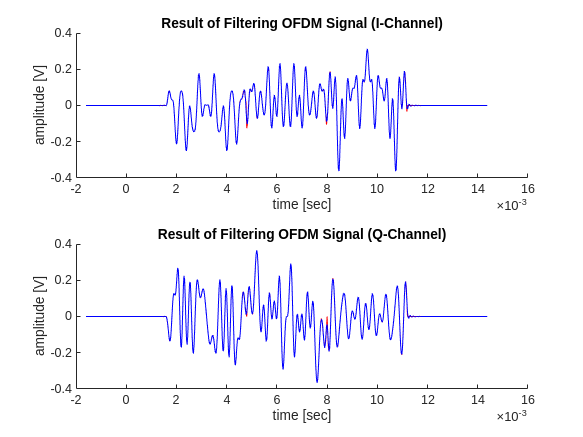


% pass the OFDM through a lowpass to meet channel specs
% define filter taps
% lp_len = 64;
% lp_taps = sqrt(2)*fir1(2*lp_len,baseband_bandwidth*2/samplerate_upsamp); 
% lp_taps = transpose(lp_taps(lp_len+1:end-1));
% s_lp = conv(lp_taps,s_upsamp_vec);
% s_lp = s_lp(1:end-lp_len+1);

% [z,p,k] = besselap(5);        % Lowpass filter prototype
% [lp_num,lp_den] = zp2tf(z,p,k);     % Convert to transfer function form

% % use 20-th order butterworth, use analog prototype and discretize with
% % bilinear transform
% b_order = 30;
% [lp_num,lp_den] = butter(b_order,baseband_bandwidth*3/samplerate_upsamp);
% 
% %[lp_den_d, lp_num_d] = bilinear(lp_num,lp_den,samplerate_upsamp);
% lp_den = transpose(lp_den);
% lp_num = transpose(lp_num);
% 
% 
% 
% % [s_lp, final] = filter(lp_den,lp_num,s_upsamp_vec);%,s_upsamp_vec(length(s_upsamp_vec)-b_order+1:end));
% s_lp = filter(lp_num,lp_den,s_zp);
% s_lp = s_lp(b_order+2:end);
% % s_lp = [s_lp(b_order+2:end);s_lp(1:b_order+1)];

% fir_length = 256;
% a = zeros(fir_length/2,1);
% a(1) = 1;
% b_full = transpose(fir1(fir_length,0.16));
% b_prescale = b_full(fir_length/2+2:end);
% lp_scale = sum(b_full)/sum(b_prescale);
% b = lp_scale*b_prescale;

wc = baseband_bandwidth*2/fs_upsamp;
filter_length = upsamp*16;
b = fir1(filter_length,wc);
a = zeros(filter_length,1);
a(1) = 1;

%[b,a] = butter(filter_order,wc);


%[b,a] = cheby2(10,50,wc);

%[b,a] = ellip(10,1,60,baseband_bandwidth*2/samplerate_upsamp);

% fir_length = 128;
% b = fir1(fir_length,baseband_bandwidth*2/samplerate_upsamp);
% a = zeros(1,fir_length);
% a(1) = 1;

% [b,a] = besself(2, 0.5, "low");
% [b,a] = bilinear(b,a,0.8);

% a = transpose(a);
% b = transpose(b);

% [h_filt, f_filt] = freqz(b,a,1000,samplerate_upsamp);
% group_delay = diff(unwrap(angle(h_filt)));
% plot(f_filt(1:end-1),group_delay);


% s_lp = ARMASYSTEM(s_upsamp_vec,b,a,0);

% filter the baseband signal
s_lp = filter(b,a,s_upsamp_vec);

% remove delay from filtered signal to compare for differences
[lp_corr,lp_corr_lags] = xcorr(s_lp,s_upsamp_vec);
delay = lp_corr_lags(lp_corr == max(lp_corr));
s_lp = [s_lp(delay+1:end); zeros(delay,1)];

%s_lp = ARMASYSTEM(s_upsamp_vec,b,a,delay);



[f_lp, spec_lp] = GetSpectrum(s_lp, fs_upsamp);
mag_spec_lp = 20*log10(abs(spec_lp));


%s_zp = [s_upsamp_vec; zeros(fir_length/8,1)];
%s_lp = [s_lp(2:end);s_lp(1)];



% % % ideal brick wall filtering
% spec_lp = spec_upsamp_all;
% spec_lp(abs(f_upsamp_all)>baseband_bandwidth) = 0;
% mag_spec_lp = 20*log10(abs(spec_lp));
% 
% % perform ifft to get back time domain message
% s_lp = ifft(ifftshift(samplerate_upsamp*spec_lp));

% calculate the mean square error before/after lowpass only on the useful
% times
MSE = 1/(s_upsamp_symbol_length * num_symbols) * sum(abs(s_lp(num_carriers*upsamp+1:end - num_carriers*upsamp)-s_upsamp_vec(num_carriers*upsamp+1:end - num_carriers*upsamp)).^2);

% plot the lowpassed version on same axes as original to show distortion
figure(3)
clf
tiledlayout
nexttile
hold on
plot(t_upsamp,real(s_upsamp_vec),'r-')
plot(t_upsamp,real(s_lp),'b-')
xlabel("time [sec]")
ylabel("amplitude [V]")
title("Result of Filtering OFDM Signal (I-Channel)")
nexttile
hold on
plot(t_upsamp,imag(s_upsamp_vec),'r-')
plot(t_upsamp,imag(s_lp),'b-')
xlabel("time [sec]")
ylabel("amplitude [V]")
title("Result of Filtering OFDM Signal (Q-Channel)")

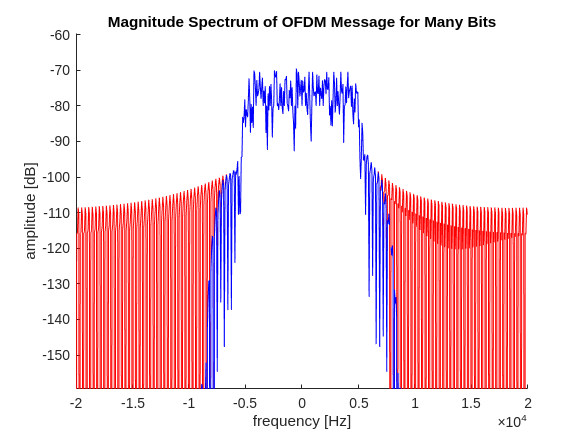


% plot the spectrum of the upsampled signal and the lowpassed version
figure(4)
clf
hold on
plot(f_upsamp_all,mag_spec_upsamp_all, 'r-')
plot(f_upsamp_all,mag_spec_lp, 'b-')
title("Magnitude Spectrum of OFDM Message for Many Bits")
xlabel("frequency [Hz]")
ylabel("amplitude [dB]")
ylim([max(mag_spec_upsamp_all)-90, max(mag_spec_upsamp_all)+10])

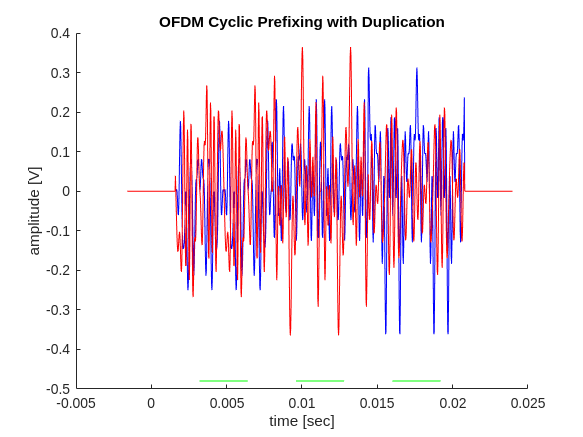


% perform cyclic prefixing/postfixing to reduce spurious emission
% duplicate each symbol for a cyclic prefix, shorten later
s_prefix = [];
for i = 1:num_symbols
    s_prefix = [s_prefix; s_upsamp(s_upsamp_symbol_length/2:end, i); s_upsamp(:, i); s_upsamp(1:s_upsamp_symbol_length/2-1, i)];
end

% zero pad the prefixed/postfixed message
s_prefix = [zeros(num_carriers*upsamp,1); s_prefix; zeros(num_carriers*upsamp,1)];

% generate time vector for prefixed/postfixed signal
n_prefix = transpose((1:length(s_prefix))-num_carriers*upsamp/2-1);
t_prefix = ts_upsamp * n_prefix;

% plot the prefix version of s(t)
figure
clf
hold on
plot(t_prefix,real(s_prefix), 'b-')
plot(t_prefix,imag(s_prefix), 'r-')
for i = 1:num_symbols
    start_bound = num_carriers*upsamp+1 + i*s_upsamp_symbol_length/2 + (i-1)*(s_upsamp_symbol_length + s_upsamp_symbol_length/2);
    end_bound = start_bound + s_upsamp_symbol_length;
    plot([t_prefix(start_bound); t_prefix(end_bound)], [-max(abs(s_prefix))-.1; -max(abs(s_prefix))-.1], 'g-')
end
title("OFDM Cyclic Prefixing with Duplication")
xlabel("time [sec]")
ylabel("amplitude [V]")


% get the spectrum of the prefixed version
[f_prefix, spec_prefix] = GetSpectrum(s_prefix,fs_upsamp);
mag_spec_prefix = 20*log10(abs(spec_prefix));

s_prefix_lp = filter(b,a,s_prefix);


% remove delay from filtered signal to compare for differences
[lp_prefix_corr,lp_prefix_corr_lags] = xcorr(s_prefix_lp,s_prefix);
delay_prefix = lp_prefix_corr_lags(lp_prefix_corr == max(lp_prefix_corr));
s_prefix_lp = [s_prefix_lp(delay_prefix+1:end); zeros(delay_prefix,1)];

%s_prefix_lp = [s_prefix_lp(b_order+2:end);s_prefix_lp(1:b_order+1)];

% % pass this prefixed version through an ideal brick-wall lowpass filter
% spec_prefix_lp = spec_prefix;
% spec_prefix_lp(abs(f_prefix)>baseband_bandwidth) = 0;
% mag_spec_prefix_lp = 20*log10(abs(spec_prefix_lp));
% 
% % perform ifft to get back time domain message
% s_prefix_lp = ifft(ifftshift(samplerate_upsamp*spec_prefix_lp));

% calculate the mean square error before/after lowpass for prefixed signal
% need to calculate only on the symbol time and not during prefix

MSE_prefix = 0;
for i = 1:num_symbols
    start_bound = num_carriers*upsamp+1 + i*s_upsamp_symbol_length/2 + (i-1)*(s_upsamp_symbol_length + s_upsamp_symbol_length/2);
    end_bound = start_bound + s_upsamp_symbol_length;
    MSE_prefix = MSE_prefix + 1/s_upsamp_symbol_length * sum(abs(s_prefix_lp(start_bound:end_bound)-s_prefix(start_bound:end_bound)).^2);
end

MSE_ratio = MSE/MSE_prefix;
fprintf("There is "); fprintf(num2str(MSE_ratio)); fprintf(" times less error through cyclic prefixing.\n")

There is 130.1052 times less error through cyclic prefixing.


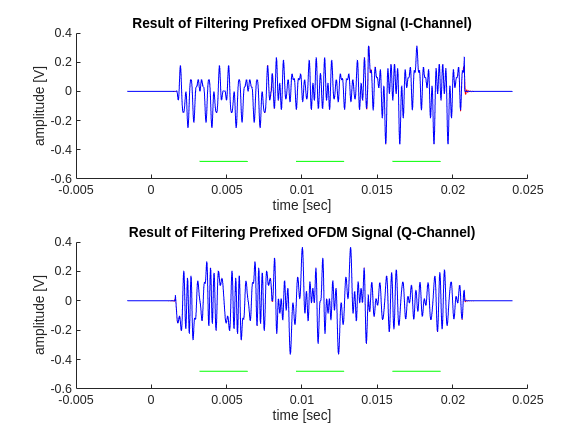

% plot the lowpassed version on same axes as original to show distortion
figure(5)
clf
tiledlayout
nexttile
hold on
plot(t_prefix,real(s_prefix_lp),'r-')
plot(t_prefix,real(s_prefix),'b-')
for i = 1:num_symbols
    start_bound = num_carriers*upsamp+1 + i*s_upsamp_symbol_length/2 + (i-1)*(s_upsamp_symbol_length + s_upsamp_symbol_length/2);
    end_bound = start_bound + s_upsamp_symbol_length;
    plot([t_prefix(start_bound); t_prefix(end_bound)], [-max(abs(s_prefix))-.1; -max(abs(s_prefix))-.1], 'g-')
end
xlabel("time [sec]")
ylabel("amplitude [V]")
title("Result of Filtering Prefixed OFDM Signal (I-Channel)")
nexttile
hold on
plot(t_prefix,imag(s_prefix_lp),'r-')
plot(t_prefix,imag(s_prefix),'b-')
for i = 1:num_symbols
    start_bound = num_carriers*upsamp+1 + i*s_upsamp_symbol_length/2 + (i-1)*(s_upsamp_symbol_length + s_upsamp_symbol_length/2);
    end_bound = start_bound + s_upsamp_symbol_length;
    plot([t_prefix(start_bound); t_prefix(end_bound)], [-max(abs(s_prefix))-.1; -max(abs(s_prefix))-.1], 'g-')
end
xlabel("time [sec]")
ylabel("amplitude [V]")
title("Result of Filtering Prefixed OFDM Signal (Q-Channel)")

## Functions:

% GetSpectrum gets the spectrum of the input signal
% uses the fftshift function to make DC appear at center term
function [f,spectrum] = GetSpectrum(samples, sample_rate)

    % determine the spectrum of the baseband signal
    spectrum = 1/sample_rate*fftshift(fft(samples));
    
    % get bin numbers (centered at 0)
    f_bins = (0:length(samples)-1) - floor(length(samples)/2);

    % define the frequency range
    f = transpose(f_bins * sample_rate / length(f_bins));
end

function bits = RandomBits(num_bits)
    % create a vector of random bits to the required length
    bits = zeros(num_bits,1);
    for i = 1:num_bits
        bits(i) = randi(2,1)-1;
    end
end